year = 2002

year = 2002


baseDir = fullfile('E:', 'University', 'EngSci Thesis', 'Thesis work');
dataDir = fullfile(baseDir, 'results','daily_area');
figureDir = fullfile(baseDir, 'figures', 'yearly_plot');

all_area = [];
all_dates = [];

for m = 1:12
    path_m = fullfile(dataDir, num2str(year), sprintf('daily_area_m%02u_y%u.mat', m, year));
    if isfile(path_m)
        S = load(path_m, 'areas', 'digital_date_ts');
        all_area = [all_area, S.areas];
        all_dates = [all_dates, S.digital_date_ts];
    else
        error_string = sprintf('File "daily_area_m%02u_y%u.mat" is missing', m, year);
        disp(error_string);
    end
end

File "daily_area_m01_y2002.mat" is missing
File "daily_area_m02_y2002.mat" is missing
File "daily_area_m03_y2002.mat" is missing
File "daily_area_m04_y2002.mat" is missing
File "daily_area_m05_y2002.mat" is missing


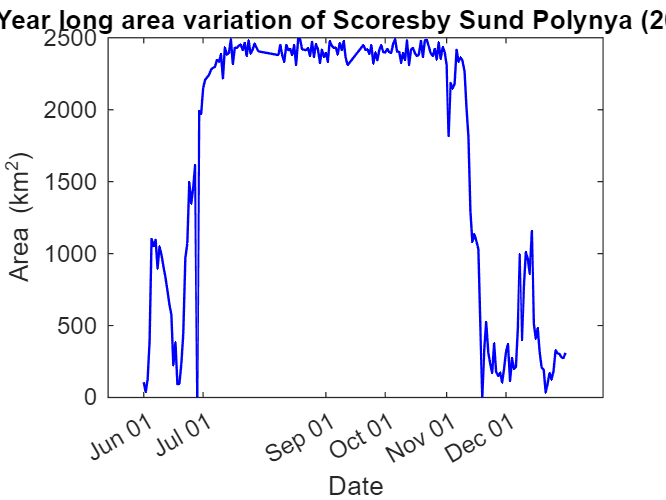


% Plot all_area against all_dates
plot(all_dates, all_area, 'Color', [0 0 1], 'LineWidth', 1);
title(sprintf('Year long area variation of Scoresby Sund Polynya (%u)', year));
xlabel('Date');
ylabel('Area (km^2)')
is_firstday = day(all_dates)==1;
xticks(all_dates(is_firstday));
xticklabels(datestr(all_dates(is_firstday), 'mmm dd')); % "Jan 01", etc.